A = double(imread("Image_2.png"));
B = A(50:249,50:249);

E = zeros(200,200);
Evertcat = [];
for j=1:200
    for i=1:200
        causalNeighborhood = [];
        if i > 1
            causalNeighborhood = [causalNeighborhood, B(i-1, j)];
        end
        if j > 1
            causalNeighborhood = [causalNeighborhood, B(i, j-1)];
        end
        if i > 1 && j > 1
            causalNeighborhood = [causalNeighborhood, B(i-1, j) + B(i, j-1) - B(i-1, j-1)];
        end
        if i == 1 && j == 1
            causalNeighborhood = [0];
        end
        E(i,j) = B(i,j) - median(causalNeighborhood);
    end
    % Concatening every column
    Evertcat = vertcat(Evertcat, E(:,j));
end

symbols = unique(Evertcat);
p = histc(Evertcat, symbols);
p = p/sum(p);
entropy = -sum(p.*log2(p))

entropy = 3.9666

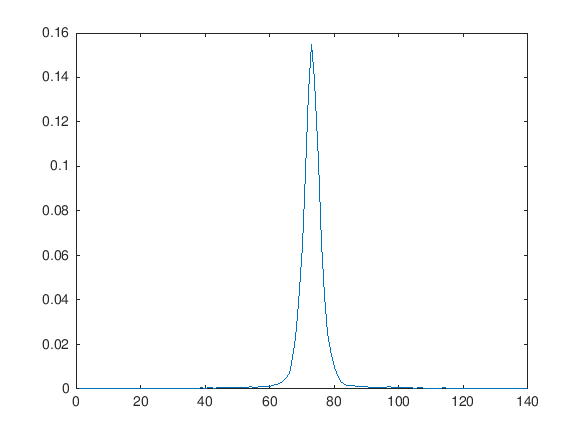


plot(p)


[dict,avglen] = huffmandict(symbols,p);
comp = huffmanenco(Evertcat,dict);

Evertcat_decoded = huffmandeco(comp, dict);
lossless = isequal(Evertcat,Evertcat_decoded)

lossless = logical
   1



CL_symb = zeros(size(symbols));
for i = 1:length(symbols)
    CL_symb(i) = length(dict{i,2});
end

% Total size, taking into consideration the space required to encode the
% dictionary
total_size = sum(CL_symb) + length(comp)

total_size = 161186


% Theorical size, using empirical probability as the average codelength
CL_huffman = sum(p.*CL_symb);

% Empirical probability
% theorical_size = floor(CL_huffman * length(Evertcat) + sum(CL_symb))

% Empiral entropy
theorical_size = floor(entropy * length(Evertcat) + sum(CL_symb))

theorical_size = 160231